% Define the file path (change 'your_file_path' to the actual path of your Excel file)
filename = 'C:\Users\azn4e\OneDrive\Desktop\University shit\EELE 489R Capstone 2\ADC_Rawdata.xlsx';

% Load the data from the Excel file
data = readtable(filename);

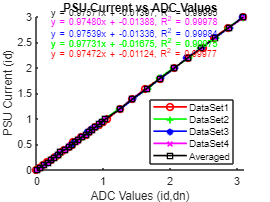

% Extract the variables by converting the table data to arrays using curly braces
id1 = data{1:31, 2};     % PSU Current
Vid_dn1 = data{1:31, 9};  % ADC values
id_dn1 = (Vid_dn1 - 0.5) / 0.8;
%-----------------------------------
id2 = data{35:65, 2};     % PSU Current
Vid_dn2 = data{35:65, 9};  % ADC values
id_dn2 = (Vid_dn2 - 0.5) / 0.8;
%-----------------------------------
id3 = data{69:99, 2};     % PSU Current
Vid_dn3 = data{69:99, 9};  % ADC values
id_dn3 = (Vid_dn3 - 0.5) / 0.8;
%-----------------------------------
id4 = data{103:133, 2};     % PSU Current
Vid_dn4 = data{103:133, 9};  % ADC values
id_dn4 = (Vid_dn4 - 0.5) / 0.8;
%-----------------------------------
% Calculate the averaged Values
ida = (id1 + id2 + id3 + id4) / 4;    % PSU Current
id_dna = (id_dn1 + id_dn2 + id_dn3 + id_dn4) / 4;

% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(id_dn1, id1, 'or-', 'LineWidth',1.5);
plot(id_dn2, id2, '+g-', 'LineWidth', 1.5);
plot(id_dn3, id3, '*b-', 'LineWidth', 1.5);
plot(id_dn4, id4, 'xm-', 'LineWidth', 1.5);
plot(id_dna, ida, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(id_dn1, id1, 'poly1');
[fit2, gof2] = fit(id_dn2, id2, 'poly1');
[fit3, gof3] = fit(id_dn3, id3, 'poly1');
[fit4, gof4] = fit(id_dn4, id4, 'poly1');
[fit_avg, gof_avg] = fit(id_dna, ida, 'poly1');

% % Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.2;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, id_dn, id, color, xOffset, yOffset) ...
    text(min(id) + xOffset, max(id_dn) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, id_dn1, id1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, id_dn2, id2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, id_dn3, id3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, id_dn4, id4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, id_dna, ida, 'k', offsetX, offsetY * 0); % Adjust multiplier as needed

% Customize the plot
title('PSU Current vs ADC Values');
xlabel('ADC Values (id,dn)');
ylabel('PSU Current (id)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

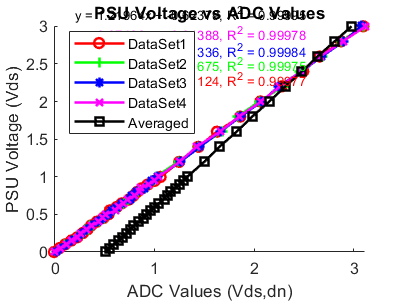

% Extract the variables by converting the table data to arrays using curly braces
Vds1 = data{1:31, 2};     % PSU Current
Vds_dn1 = data{1:31, 9};  % ADC values
Vdsr_dn1 = (Vds_dn1 - 0.5) / 0.8;
%-----------------------------------
Vds2 = data{35:65, 2};     % PSU Current
Vds_dn2 = data{35:65, 9};  % ADC values
Vdsr_dn2 = (Vds_dn2 - 0.5) / 0.8;
%-----------------------------------
Vds3 = data{69:99, 2};     % PSU Current
Vds_dn3 = data{69:99, 9};  % ADC values
Vdsr_dn3 = (Vds_dn3 - 0.5) / 0.8;
%-----------------------------------
Vds4 = data{103:133, 2};     % PSU Current
Vds_dn4 = data{103:133, 9};  % ADC values
Vdsr_dn4 = (Vds_dn4 - 0.5) / 0.8;
%-----------------------------------
% Calculate the averaged Values
Vdsa = (Vds1 + Vds2 + Vds3 + Vds4) / 4;    % PSU Current
Vdsr_dna = (Vds_dn1 + Vds_dn2 + Vds_dn3 + Vds_dn4) / 4;

% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(Vdsr_dn1, Vds1, 'or-', 'LineWidth',1.5);
plot(Vdsr_dn2, Vds2, '+g-', 'LineWidth', 1.5);
plot(Vdsr_dn3, Vds3, '*b-', 'LineWidth', 1.5);
plot(Vdsr_dn4, Vds4, 'xm-', 'LineWidth', 1.5);
plot(Vdsr_dna, Vdsa, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(Vdsr_dn1, Vds1, 'poly1');
[fit2, gof2] = fit(Vdsr_dn2, Vds2, 'poly1');
[fit3, gof3] = fit(Vdsr_dn3, Vds3, 'poly1');
[fit4, gof4] = fit(Vdsr_dn4, Vds4, 'poly1');
[fit_avg, gof_avg] = fit(Vdsr_dna, Vdsa, 'poly1');

% Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.2;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, Vdsr_dn, Vds, color, xOffset, yOffset) ...
    text(min(Vds) + xOffset, max(Vdsr_dn) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, Vdsr_dn1, Vds1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, Vdsr_dn2, Vds2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, Vdsr_dn3, Vds3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, Vdsr_dn4, Vds4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, Vdsr_dna, Vdsa, 'k', offsetX, offsetY*-1); % Adjust multiplier as needed

% Customize the plot
title('PSU Voltage vs ADC Values');
xlabel('ADC Values (Vds,dn)');
ylabel('PSU Voltage (Vds)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot